clear all

Xgrid=400

Xgrid = 400

Ygrid=400

Ygrid = 400

for x=1:Xgrid
    for y=1:Ygrid
        for model=1:2
            for react=1:95
                fluxes{x}{y}{model}(react)=0;
            end
        end
    end
end


am1e_5Cn5_5e_5_at5500

f=figure 

f =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [488 242 560 420]
       Units: 'pixels'

  Show all properties


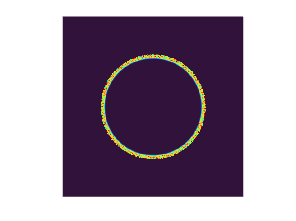

%maxflux=max(ammonia_flux{:}{:}{:})
%minflux=min(ammonia_flux{:}{:}{:})
maxflux=0;
minflux=-10;
C(1:Xgrid,1:Ygrid)=0;
for x=1:Xgrid
    for y=1:Ygrid
        C(x,y)=0;
        %C(x,y,1)=-255*fluxes{x}{y}{1}(35)/10;
        %C(x,y,2)=-255*fluxes{x}{y}{1}(35)/10;
        %C(x,y,3)=-255*fluxes{x}{y}{2}(35)/10;
        C(x,y)=fluxes{x}{y}{1}(35)+fluxes{x}{y}{2}(35);
        %C(x,y,1)=0;
        %C(x,y,2)=0;
        %C(x,y,3)=0;
        %if C(x,y,1)~=0 && C(x,y,2)~=0
        %C(x,y,1)=C(x,y,1)/(C(x,y,1)+0.5);
        %C(x,y,2)=C(x,y,2)/(C(x,y,2)+0.5);
        %C(x,y,1)=alpha*C(x,y,1)+beta;
        %C(x,y,2)=alpha*C(x,y,2)+beta;
        %end
    end
end

%heatmap(C)
s=image(-255*C/10);
%colorbar
%s=pcolor(1:Xgrid,1:Ygrid,-C)
%hold on
%s.EdgeColor = 'none';
ax=gca;
%zlim([0 3]);
ax.Box = 'off';
ax.XGrid = 'off';
ax.YGrid = 'off';
ax.ZGrid = 'off';
ax.XTick = [];
ax.YTick = [];
ax.ZTick = [];
ax.ZColor = 'none';
ax.YColor = 'none';
ax.XColor = 'none';
colormap(ax,turbo);
axis equal

%view(azymuth,elevation)hh
%clear var

exportgraphics(f,"am1e-5Cn5.5e-5_at5500.png",'Resolution', 300)

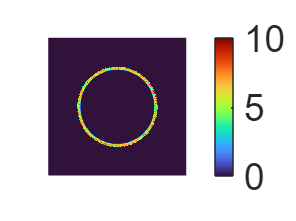

colorbar('Ticks',[1,128,255],'TickLabels',{'0','5','10'},FontSize=20)
exportgraphics(f,"am1e-5Cn5.5e-5_at5500_wBar.png",'Resolution', 300)